# 線形回帰による母音の識別

## 準備

はじめに，音声の計測のため，マイク等のセットアップをします．

fs = 8000;
mic = audioDeviceReader('SampleRate', fs);

次に，データの準備をします．

rec_dur = 10;
clip_length = 1024;

まず，「あ」と言っている間の音声を計測します．

record_a = [];

input('Press any key to start /a/')
tstart = tic;
wb = waitbar(0, ['Speak /a/ for ', int2str(rec_dur), ' sec.']);
while toc(tstart) < rec_dur
    waitbar(toc(tstart)/rec_dur, wb)
    audio = step(mic);
    record_a = vertcat(record_a, audio);
end
disp('stop /a/')

stop /a/


delete(wb)

record_a = record_a(fs:end-fs);
n_sample_a = length(record_a);
n_record_a = floor(n_sample_a/clip_length);
record_a = reshape(record_a(1:clip_length*n_record_a), [clip_length, n_record_a]);

それから，「い」と言っている間の音声を計測します．

record_i = [];

input('Press any key to start /i/')
tstart = tic;
wb = waitbar(0, ['Speak /i/ for ', int2str(rec_dur), ' sec.']);
while toc(tstart) < rec_dur
    waitbar(toc(tstart)/rec_dur, wb);
    audio = step(mic);
    record_i = vertcat(record_i, audio);
end
disp('stop /i/')

stop /i/


delete(wb)

record_i = record_i(fs:end-fs);
n_sample_i = length(record_i);
n_record_i = floor(n_sample_i/clip_length);
record_i = reshape(record_i(1:clip_length*n_record_i), [clip_length, n_record_i]);

最後に，モデルの学習のため，データをFFTして，ラベルを用意します．

records = horzcat(record_a, record_i);
records_f = abs(fft(records));
records_f = records_f(1:length(records_f)/2+1, :)';
f = (fs*(0:(clip_length/2))/clip_length)';
disp('# of dimensions of data')

# of dimensions of data


disp(size(records_f))

   123   513




label_a = ones(1, n_record_a);
label_i = zeros(1, n_record_i);
labels = horzcat(label_a, label_i)';
disp('# of dimensions of label')

# of dimensions of label


disp(size(labels))

   123     1



## L1正則化をつけた線形回帰モデル（LASSO）

母音の「あ」と「い」の音声を分類することを考えます．単純な線形回帰では2値分類に適さないため，線形回帰モデルの出力に二項分布を追加します．また，多次元な入力のうち一部の次元だけが分類に貢献すると考える場合，L1正則化をつけた線形回帰モデル（LASSO）を用いることで，一部の次元にのみ重みを割り当てることができます．ここでは，LASSOを用いて母音の分類モデルを構築します．

disp('Making coefficients...')

Making coefficients...


[B, fit_info] = lassoglm(records_f, labels, 'binomial', 'CV', 3);
idx_min_dev = fit_info.IndexMinDeviance;
B0 = fit_info.Intercept(idx_min_dev);
coef = [B0; B(:, idx_min_dev)];
disp('Done')

Done



% lassoPlot(B, fit_info, 'PlotType', 'CV');
% legend('show');

学習済みモデルの学習データに対する分類結果を確認します．

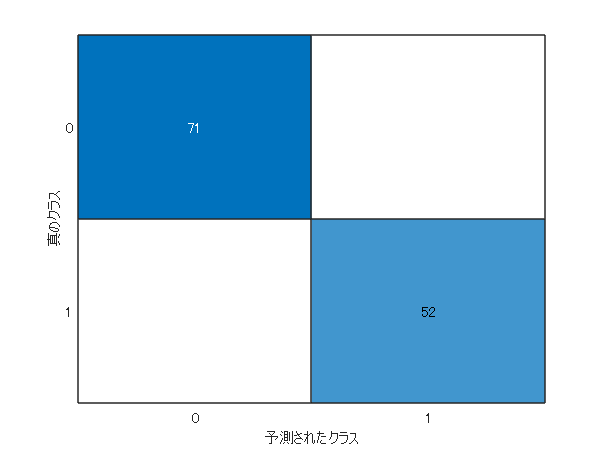

pred = glmval(coef, records_f, 'logit');
pred(pred >= 0.5) = 1;
pred(pred < 0.5) = 0;
figure;
c = confusionchart(labels, pred);

LASSOによって得られた重みから，どの周波数の情報が分類に寄与したかを確認してみます．

coef_threshold = 0.1;
disc_idx_p = find(coef > coef_threshold);
disc_idx_n = find(coef < - coef_threshold);
disc_idx = vertcat(disc_idx_p, disc_idx_n);

f_disc_p = f(disc_idx_p);
f_disc_n = f(disc_idx_n);
disp('positive (frequency & coefficient)')

positive (frequency & coefficient)


disp(f_disc_p')

  125.0000  210.9375  335.9375  453.1250  593.7500  601.5625  609.3750  617.1875  664.0625  679.6875  695.3125  929.6875



disp(coef(disc_idx_p)')

    1.7221    1.9787    0.4381    0.3039    0.6970    0.5355    0.2398    0.5349    4.0042    0.2868    1.4885    0.2694



disp('negative (frequency & coefficient)')

negative (frequency & coefficient)


disp(f_disc_n')

   1.0e+03 *

         0    0.2656    0.2734    2.0312    2.2031    3.2734



disp(coef(disc_idx_n)')

   -4.0602   -0.2035   -0.2796   -0.9665   -0.6330   -0.7518



f_disc = vertcat(f_disc_p, f_disc_n);

## 後片付け

release(mic)